### Introduction

### **Equations**

**Governing Equation**

The governing partial differential equation for the one-dimensional model is as follows:


$$\frac{\partial T}{\partial t}=\frac{1}{A\left(z\right)}\frac{\partial }{\partial z}\left\lbrace A\left(z\right)\left\lbrack \kappa_m +K\left(z,t\right)\right\rbrack \frac{\partial T}{\partial z}\right\rbrace +\frac{1}{A\left(z\right)}\frac{1}{c_w }\frac{\partial }{\partial z}\left(\Phi A\left(z\right)\right)$$


- Where T is water temperature (ºC)

- t is time (days)

- z is depth from the surface (m)

- κ_m is the molecular diffusion of water (m^2 day^-1)

- K(z,t) is eddy diffusivity (m^2 day^-1)

- $c_w$ is the volumetric heat capacity of water (J m^-3 ºC^-1)

- Φ is a heat source term (W m^-2)

- A(z) is the surface area of the lake at depth z.

#### Surface boundary condition

The surface boundary condition is:


$$\left\lbrack \kappa_m +K\left(z,t\right)\right\rbrack \frac{\partial T}{\partial z}=K^* +L_d^* -L_u \pm Q_e \pm Q_h$$


- $L_d^*$ is net longwave radiation from the atmosphere (W m^-2)

- $L_u$ is longwave radiation from the lake surface (W m^-2)

- $Q_e$ is flux of latent heat (W m^-2)

- $Q_h$ is flux of sensible heat (W m^-2)

#### Bottom boundary condition for insulated lake bottom

For an insulated lake bottom, the bottom boundary condition is:


$$\left\lbrack \kappa_m +K\left(z,t\right)\right\rbrack \frac{\partial T}{\partial z}=0$$


### Numerical Methods

We chose to use the Forward Euler method.

#### Constant diffusivity, only bottom boundary condition  

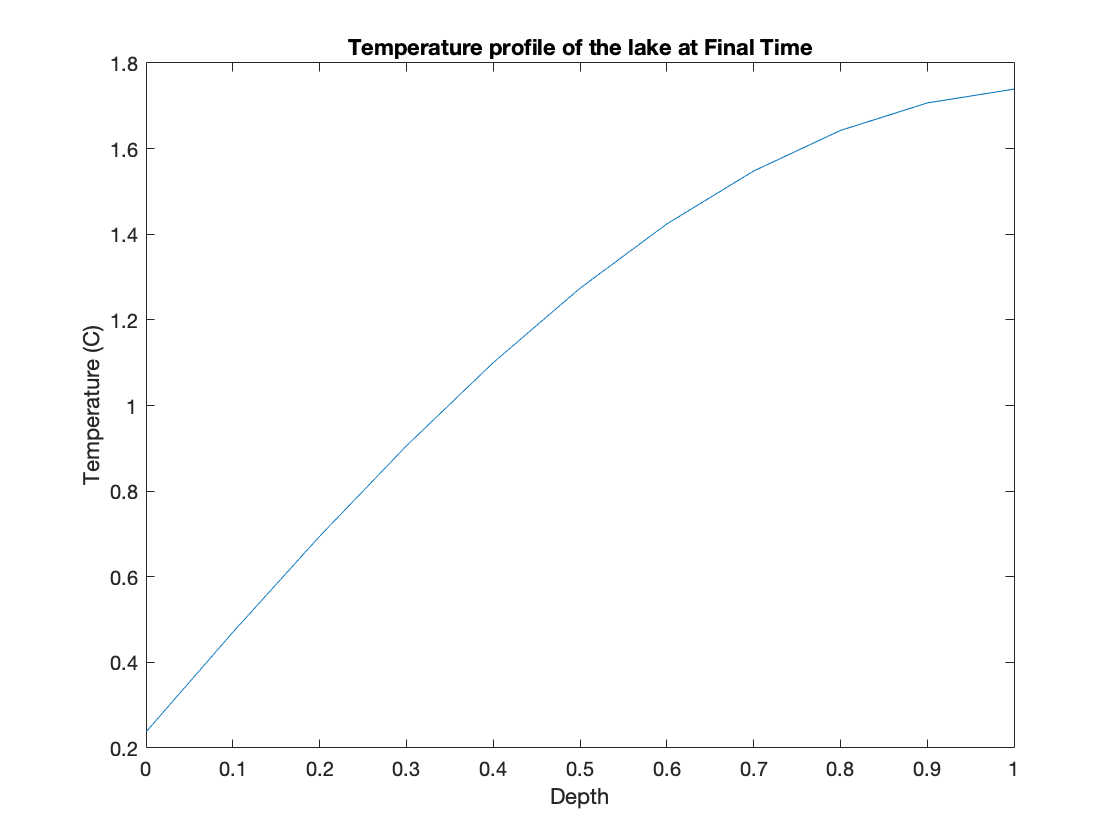

dz = 0.1; %depth grid spacing (m)
zf = 1; % lake depth in meters
zs = 0:dz:zf; % vector of depths in the lake

dt = 86400; % time grid spacing = 1 day
tf = 3600*24*365*3; % 3 years
ts = 0:dt:tf;

D = 1e-8; %hard coded to something small enough that CD < 0.5

C_D = D*dt/(dz)^2;


% Forward Euler method

M = sparse(length(zs),length(zs));

% create matrix

for i = 1:length(zs)
    for j = 1:length(zs)
        if i==j
            M(i,j) = 1-2*C_D;
        elseif i-1==j
            M(i,j) = C_D;
        elseif i+1==j
            M(i,j) = C_D;
        end
    end
end


M(end,end-1)=C_D;
M(end,end) = 1-C_D;


% Pre-allocate

T_all = nan(length(zs), length(ts));
T = 8 .* ones(length(zs), 1); %initial T throughout lake is annual avg 8C
T_all(:,1) = T;

% Forward Euler Diffusion

for k = 1:length(ts)-1
    Tnew = M*T;
    
    T_all(:,k+1) = Tnew;
    T = Tnew;
end

% plot

figure(1);
plot(zs, T_all(:,length(ts))) % end
title('Temperature profile of the lake at Final Time')
xlabel('Depth')
ylabel('Temperature (C)')

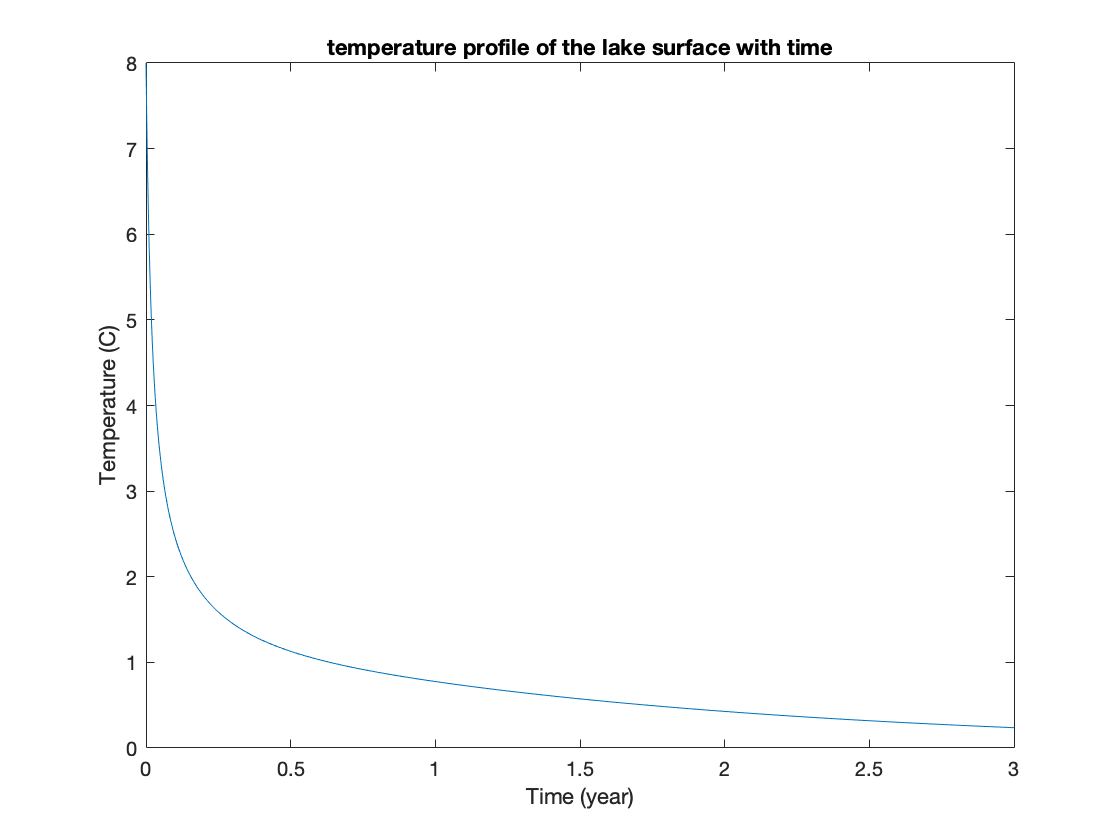


figure(2)
plot(ts/86400/365, T_all(1, :))
title('temperature profile of the lake surface with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

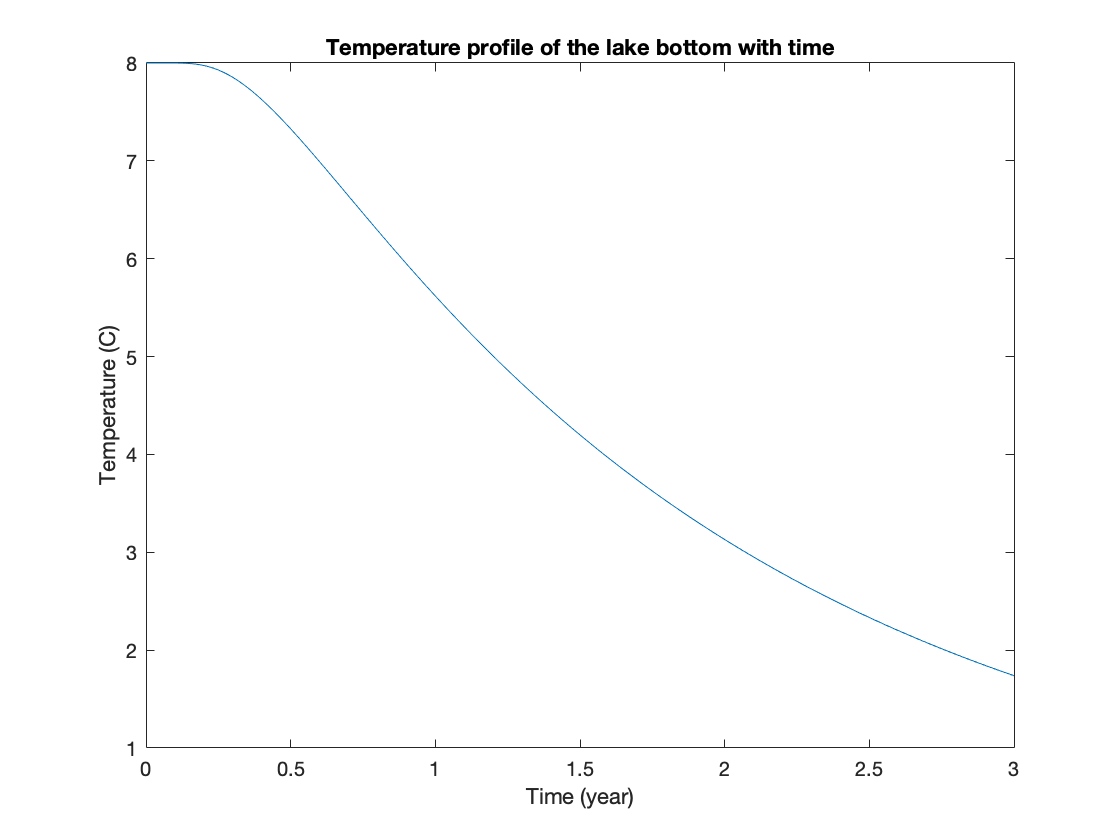


figure(3)
plot(ts/86400/365, T_all(end, :))
title('Temperature profile of the lake bottom with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

#### Constant diffusivity, both boundary conditions

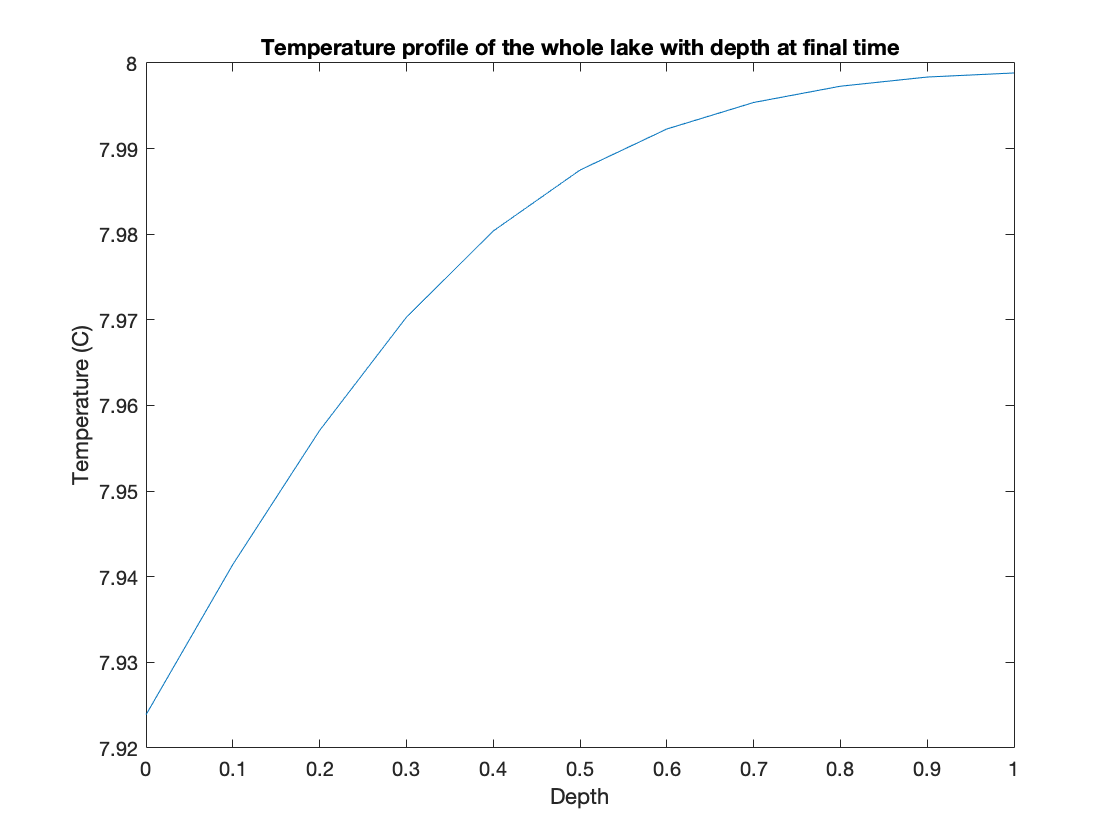

% Parameters and constants

dz = 0.1; %depth grid spacing (m)
zf = 1; % lake depth in meters
zs = 0:dz:zf; % vector of depths in the lake

dt = 86400; % time grid spacing = 1 day
tf = 3600*24*365*3; % 3 years
ts = 0:dt:tf;

D = 1e-9; %hard coded to something small enough that CD < 0.5

C_D = D*dt/(dz)^2;

conductivity = 0.5918; % W m^-1 K^-1 - slightly less than the value at 10C

% Net incoming shortwave radiation:

Kstar = @(t) 500+100*sin(2*pi*t/(365*86400));
% assume all radiation absorbed is right at the surface: e^(eta*z)=0

% Net longwave radiation:
epsilon = 0.97;
sigma = 5.67e-8;
% assume longwave radiation out with constant temp 8C
L_u = epsilon*sigma* (8 + 273.15)^4;

% Assume flux of sensible and latent heat are zero
Q_e = 0;
Q_h = 0;

%Total heat balance
heat = @(t) Kstar(t) - L_u + Q_e + Q_h;

% Forward Euler method

M = sparse(length(zs),length(zs));

% create matrix

for i = 1:length(zs)
    for j = 1:length(zs)
        if i==j
            M(i,j) = 1-2*C_D;
        elseif i-1==j
            M(i,j) = C_D;
        elseif i+1==j
            M(i,j) = C_D;
        end
    end
end

M(1,1) = 1-C_D;
M(1,2) = C_D;
M(end,end-1)=C_D;
M(end,end) = 1-C_D;


% Pre-allocate

T = 8 .* ones(length(zs), 1); %initial T throughout lake is annual avg 8C

T_all = nan(length(zs), length(ts));
T_all(:,1) = T;

known_vec = zeros(length(zs), 1);

% Forward Euler Diffusion

for k = 1:length(ts)-1
    
    F_sfc = heat(ts(k))/conductivity;
    
    known_vec(1) = -C_D*dz*F_sfc;
    
    Tnew = M*T + known_vec;
    
    T_all(:,k+1) = Tnew;
    T = Tnew;
end

% plot

figure(4);
plot(zs, T_all(:,length(ts))) % end
title('Temperature profile of the whole lake with depth at final time')
xlabel('Depth')
ylabel('Temperature (C)')

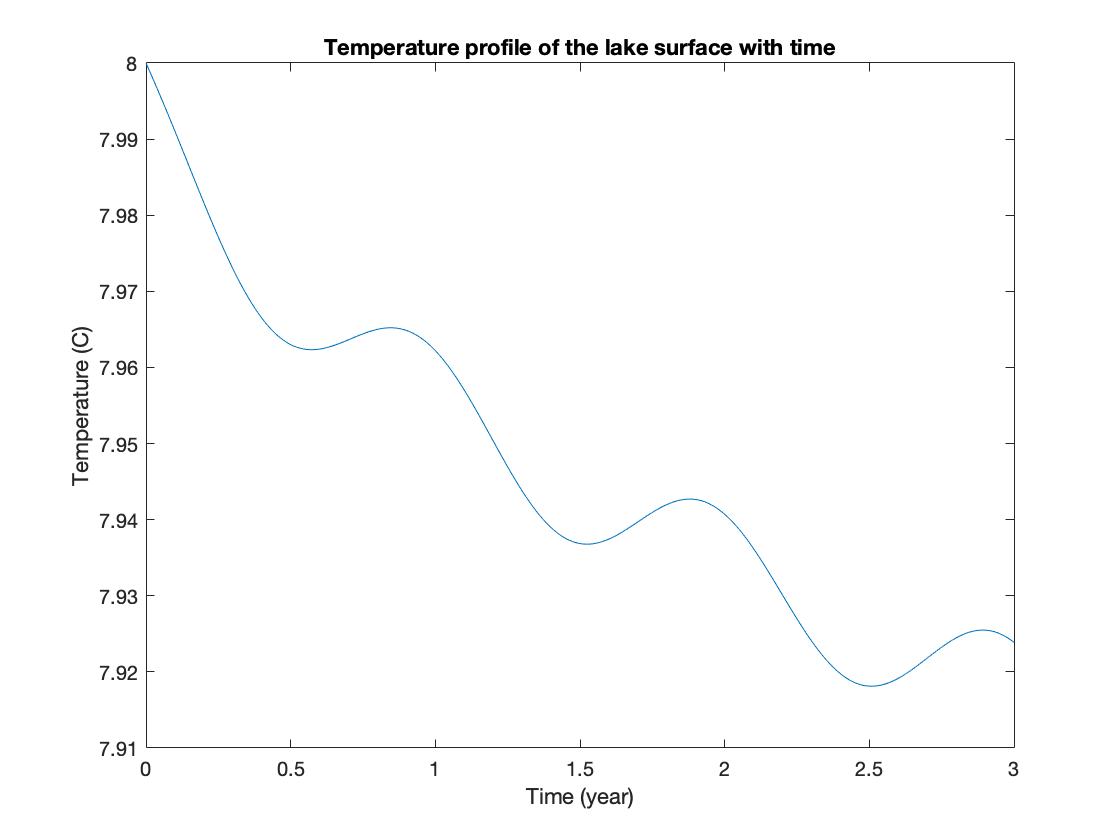


figure(5)
plot(ts/86400/365, T_all(1, :))
title('Temperature profile of the lake surface with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

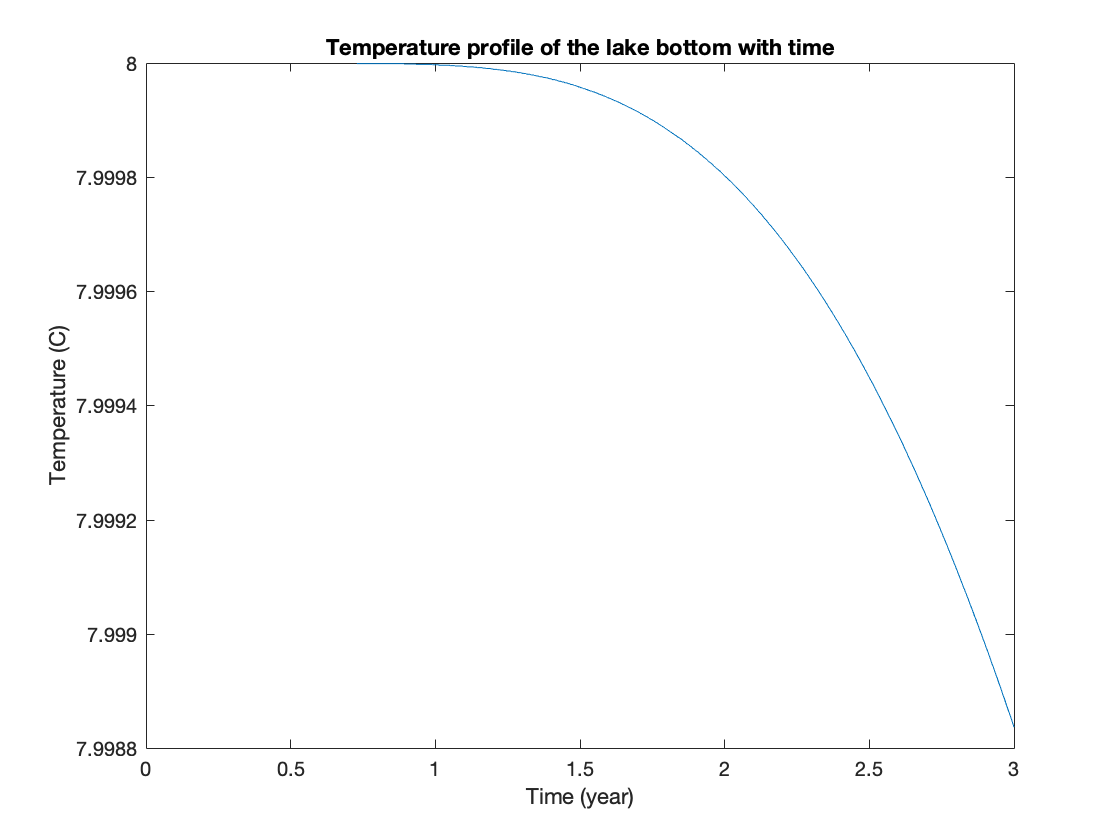


figure(6)
plot(ts/86400/365, T_all(end, :))
title('Temperature profile of the lake bottom with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

#### Varying diffusivity, both boundary conditions

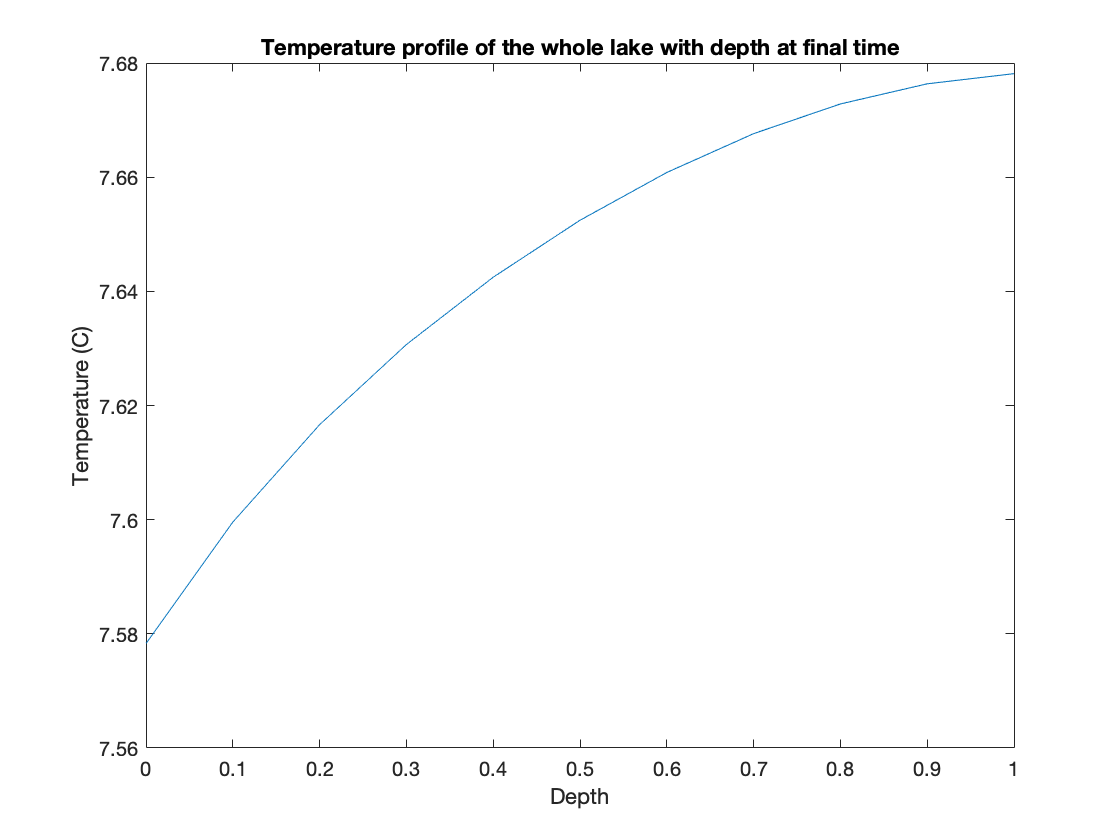


% Equation caluculated in Google Sheets from values in R. Mills (1973)

kappa_m = @(T_k) (16.4 - 0.151*T_k + 3.48e-4*T_k^2)*1e-9;

%% Parameters and constants

dz = 0.1; %depth grid spacing (m)
zf = 1; % lake depth in meters
zs = 0:dz:zf; % vector of depths in the lake

dt = 86400; % time grid spacing = 1 day
tf = 3600*24*365*3; % 3 years
ts = 0:dt:tf;

conductivity = 0.5918; % W m^-1 K^-1 - slightly less than the value at 10C

% Net incoming shortwave radiation:

Kstar = @(t) 500+100*sin(2*pi*t/(365*86400));
% assume all radiation absorbed is right at the surface: e^(eta*z)=0

% Net longwave radiation:
epsilon = 0.97;
sigma = 5.67e-8;
% assume longwave radiation out with constant temp 8C
L_u = epsilon*sigma* (8 + 273.15)^4;

% Assume flux of sensible and latent heat are zero
Q_e = 0;
Q_h = 0;

%Total heat balance
heat = @(t) Kstar(t) - L_u + Q_e + Q_h;

%% Pre-allocate

T = 8 .* ones(length(zs), 1); %initial T throughout lake is annual avg 8C

T_all = nan(length(zs), length(ts));
T_all(:,1) = T;

known_vec = zeros(length(zs), 1);

%% Loop

for k = 1:length(ts)-1

    D = kappa_m(T(1));

    C_D = D*dt/(dz)^2;

    % Forward Euler method

    M = sparse(length(zs),length(zs));

    % create matrix

    for i = 1:length(zs)
        for j = 1:length(zs)
            if i==j
                M(i,j) = 1-2*C_D;
            elseif i-1==j
                M(i,j) = C_D;
            elseif i+1==j
                M(i,j) = C_D;
            end
        end
    end

    M(1,1) = 1-C_D;
    M(1,2) = C_D;
    M(end,end-1)=C_D;
    M(end,end) = 1-C_D;

    % Forward Euler Diffusion

    
    F_sfc = heat(ts(k))/conductivity;
    
    known_vec(1) = -C_D*dz*F_sfc;
    
    Tnew = M*T + known_vec;
    
    T_all(:,k+1) = Tnew;
    T = Tnew;
end

% plot

figure(7);
plot(zs, T_all(:,length(ts))) % end
title('Temperature profile of the whole lake with depth at final time')
xlabel('Depth')
ylabel('Temperature (C)')

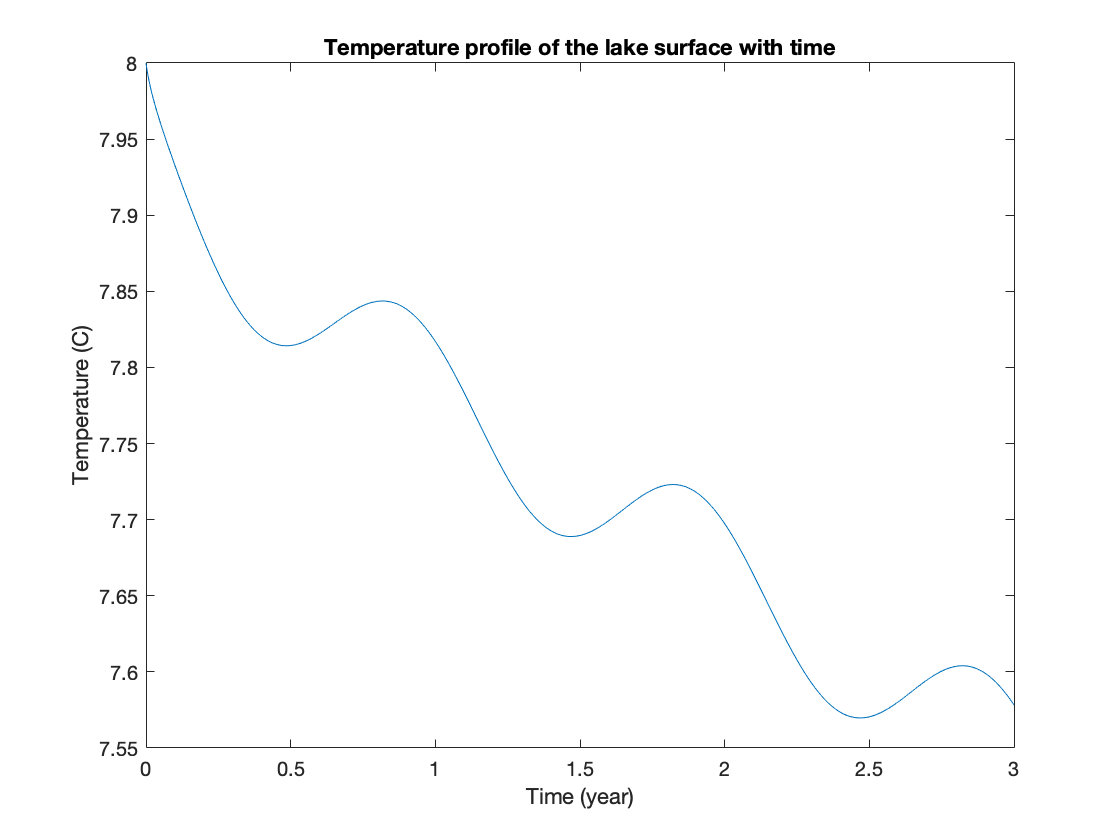


figure(8)
plot(ts/86400/365, T_all(1, :))
title('Temperature profile of the lake surface with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

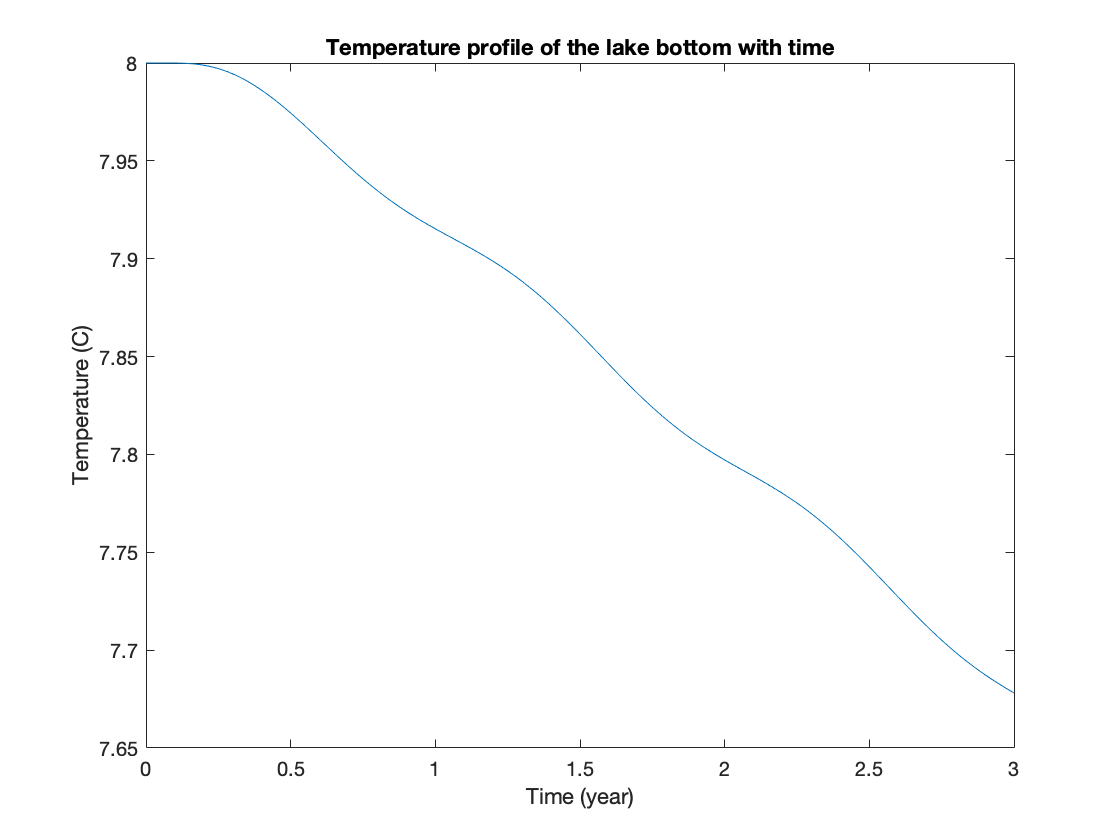


figure(9)
plot(ts/86400/365, T_all(end, :))
title('Temperature profile of the lake bottom with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

### Results

### Conclusions